Our research focuses on the comparison of precipitation levels on a yearly basis between data measured at the Vancouver Harbour Weather Station and Vancouver's predicted precipitation by the CMIP5 climate model. The CMIP5 climate model is a coordinated climate modeling exercise involving 20 climate-modeling groups from around the world and has provided a standard experimental protocol for producing and studying the output of many different global climate models. From the CMIP5 climate model datasets, we chose datasets relating to different Representative Concentration Pathways (RCP), which represents scenarios with different concentrations of greenhouse gas (GHG) emissions, allows scientists to model climate change to build scenarios about the impacts of climate change and to help plan for the future.

Code used to import the Climate Station Data file into MATLAB, create variables for each of the corresponding columns, and create a plot to display Date vs Total Precipitation.

fid = fopen('C:\Users\Nelso\OneDrive\Documents\EOSC 442\climateStationData.csv');
format1 = ['%f %f %s %f %s %s %s %f %f %f %f %s %f %s %f %s %f %s %f %s %f %s %f %s %f %s %f %s %f %s %f %s %f %s %f %s'];
climate_data = textscan(fid, format1, 'HeaderLines', 1, 'Delimiter', ',');

cdate = climate_data{6};
cday = climate_data{10};
cmonth = climate_data{9};
cyear = climate_data{8};
dailymeantemp = climate_data{11};
tot_prep = climate_data{17};
tot_rain = climate_data{19};
tot_snow = climate_data{21};

ddate = [cyear, cmonth, cday];
date_update = datenum(cdate, 'yyyy-mm-dd HH:MM:SS');

figure(1);
plot(date_update, tot_prep);
datetick('x', 'yyyy-mm-dd', 'keepticks');
title('Total Precipitation vs Date');
ylabel('Total Precipitation', 'FontSize', 10);
txt={'Date','Figure 1: Daily Time Series of Total Precipitation at the Vancouver Harbour CS from 1957 to 2022'}

txt = 1×2 cell array
    {'Date'}    {'Figure 1: Daily Time Series of Total Precipitation at the Vancouver Harbour CS from 1957 to 2022'}


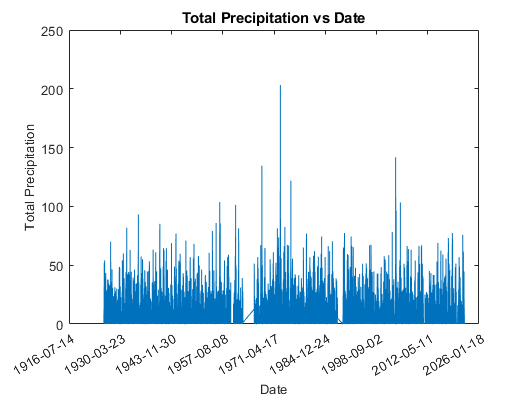

xlabel('Date', 'FontSize', 10);

Looking at the Climate Model data, we find that it gives its predictions by year which is problematic as the climate station data is taken by day.  

To get a better understanding of the data, we use the code below is used to convert the daily data from the Vancouver Harbour Station to total precipitation per month from 1925 to 2022, then later convert it to total precipitation per year. 

D = [cyear, cmonth, cday, tot_prep];
D(any(isnan(D), 2), :) = [];

k=1

k = 1

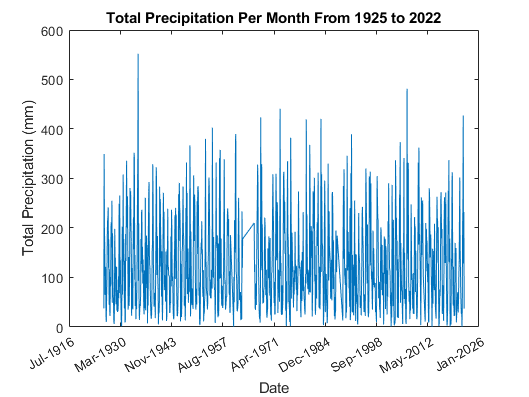

  %Total Precipitation Per Month From 1925 to 2022
  for z = 1925:2022                                     %Years Looping
      for y = 1:12                                      %Months Looping
          ydx = find((D(:,2)==y) & (D(:,1)==z));        %Find all indeces for the specific month
          sumdata1 = sum(D(ydx,4),1);
          MonthlyAvg(k,:) = [y,z,sumdata1;];            %Store in the mean values per month in a new matrix
          k=k+1;
      end
  end

MonthlyAvg(any(isnan(MonthlyAvg), 2), :) = [];
MonthlyAvg(any(MonthlyAvg==0,2), :) = [];
Fixdate = datenum([MonthlyAvg(:,2), MonthlyAvg(:,1), ones(1068,1)]);

figure(2);
plot(Fixdate, MonthlyAvg(:,3));
title('Total Precipitation Per Month From 1925 to 2022');
xlabel('Date');
ylabel('Total Precipitation (mm)');
datetick('x', 'mmm-yyyy', 'keepticks');

After finding the totals per month, we use the code below to calculate the average total precipitation per month along with the standard deviations, max's and min's for the data. 

MonthlyAvgFix = [Fixdate MonthlyAvg]

MonthlyAvgFix = 1.0e+05 *

    7.0340    0.0001    0.0192    0.0004
    7.0343    0.0001    0.0192    0.0035
    7.0346    0.0000    0.0193    0.0020
    7.0349    0.0000    0.0193    0.0017
    7.0352    0.0000    0.0193    0.0006
    7.0355    0.0000    0.0193    0.0007
    7.0358    0.0001    0.0193    0.0012
    7.0361    0.0001    0.0193    0.0002
    7.0364    0.0001    0.0193    0.0001
    7.0367    0.0001    0.0193    0.0006


a=1

a = 1

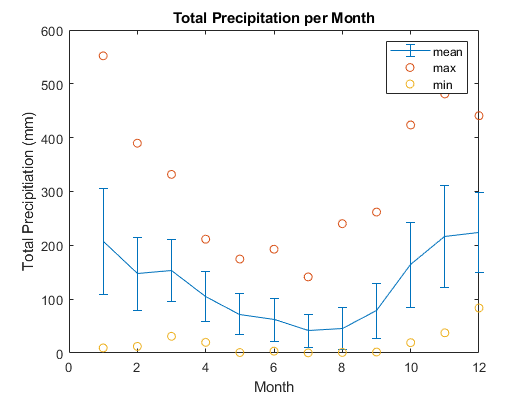

  %Calculating Average Total Precipitation per Month
  for c = 1925:2022                                     %Years Looping
      for b = 1:12                                      %Months Looping
          bdx = find(MonthlyAvgFix(:,2)==b);            %indices for spec month
          meandata = mean(MonthlyAvgFix(bdx,4),1);
          stddata = std(MonthlyAvgFix(bdx,4));
          maxdata = max(MonthlyAvgFix(bdx,4));
          mindata = min(MonthlyAvgFix(bdx,4));
          monthavgtot(b,:) = [b,c,meandata, stddata, maxdata, mindata;];           %Store in a new matrix the mean values per month b,c,sumdata, stddata, maxdata, mindata;];
          b=b+1;
      end
  end

figure(3);
errorbar(monthavgtot(:,1), monthavgtot(:,3), monthavgtot(:,4))
hold on
plot(monthavgtot(:,1), monthavgtot(:,5), 'o');
plot(monthavgtot(:,1), monthavgtot(:,6), 'o');
hold off
title('Total Precipitation per Month');
xlabel('Month');
ylabel('Total Precipitiation (mm)');
legend('mean', 'max', 'min');

Climate Model Data

Code used to import the csv files and of three different trajectories of modeled RCP data, then create a variable containing the data points, their corresponding dates, and a plot showing the Predicted Yearly precipitation for each Model.

fid2 = fopen('C:\Users\Nelso\OneDrive\Documents\EOSC 442\ClimateModelDataAnnual.csv');
format2 = ['%s %f %f %f %f %f %f %f %f %f %f %f %f' ];
climatemodeldata = textscan(fid2, format2, 'HeaderLines', 1, 'Delimiter', ',');

modeldate = climatemodeldata{1};
modeldateupdate = datenum(modeldate, 'yyyy-mm-dd');
formatIn =  'yyyy-MM-dd'

formatIn = 'yyyy-MM-dd'

modeldate_update = datevec(modeldate, formatIn);

rcp26_prcptot_p10 = climatemodeldata{4};
rcp26_prcptot_p50 = climatemodeldata{5};
rcp26_prcptot_p90 = climatemodeldata{6};
rcp45_prcptot_p10 = climatemodeldata{7};
rcp45_prcptot_p50 = climatemodeldata{8};
rcp45_prcptot_p90 = climatemodeldata{9};
rcp85_prcptot_p10 = climatemodeldata{10};
rcp85_prcptot_p50 = climatemodeldata{11};
rcp85_prcptot_p90 = climatemodeldata{12};

modeldatavar = [modeldate_update,  rcp26_prcptot_p90, rcp45_prcptot_p90, rcp85_prcptot_p90 ]

modeldatavar = 1.0e+03 *

    1.9500    0.0010    0.0010         0    0.0010         0    2.0172    2.0172    2.0172
    1.9510    0.0010    0.0010         0    0.0010         0    1.7304    1.7304    1.7304
    1.9520    0.0010    0.0010         0    0.0010         0    1.8761    1.8677    1.8760
    1.9530    0.0010    0.0010         0    0.0010         0    1.8647    1.8645    1.8637
    1.9540    0.0010    0.0010         0    0.0010         0    1.9685    1.9634    1.9648
    1.9550    0.0010    0.0010         0    0.0010         0    1.7671    1.7656    1.7692
    1.9560    0.0010    0.0010         0    0.0010         0    1.8824    1.8853    1.8823
    1.9570    0.0010    0.0010         0    0.0010         0    1.8252    1.8252    1.8252
    1.9580    0.0010    0.0010         0    0.0010         0    1.8525    1.8489    1.8453
    1.9590    0.0010    0.0010         0    0.0010         0    2.0173    2.0200    2.0154


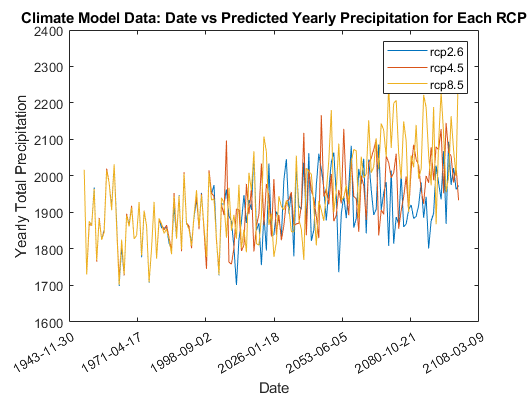

figure(4);
plot(modeldateupdate, rcp26_prcptot_p90);
hold on;
plot(modeldateupdate, rcp45_prcptot_p90);
plot(modeldateupdate, rcp85_prcptot_p90);
hold off;
title('Climate Model Data: Date vs Predicted Yearly Precipitation for Each RCP');
xlabel('Date');
ylabel('Yearly Total Precipitation');
legend('rcp2.6', 'rcp4.5', 'rcp8.5');
datetick('x', 'yyyy-mm-dd', 'keepticks');

As mentioned earlier, the section below creates a matrix containing the total precipitation of each year by summing all the data points within each given year. 

j=1

j = 1

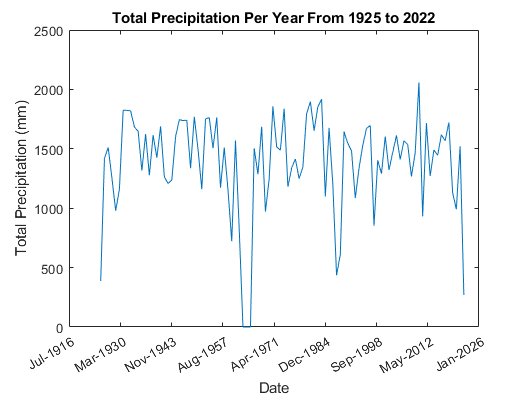

  %Total Precipitation Per Year From 1925 to 2022
  for yr = 1925:2022                                     %Years Looping
          yrdx = find(D(:,1)==yr);                       %Find all indeces for the specific month
          yearlysumdata1 = sum(D(yrdx,4),1);
          YearlyAvg(j,:) = [yr,yearlysumdata1;];         %Store in a new matrix the mean values per month
          j=j+1;

  end

Fixdateyear = datenum([YearlyAvg(:,1),  ones(98,1), ones(98,1)]);

figure(5);
plot(Fixdateyear, YearlyAvg(:,2));
title('Total Precipitation Per Year From 1925 to 2022');
xlabel('Date');
ylabel('Total Precipitation (mm)');
datetick('x', 'mmm-yyyy', 'keepticks');

With the two datasets, Climate Station Data and RCP data, having different years, we create a new matrix containing the data in which both overlap, then plot the points on top of each other.

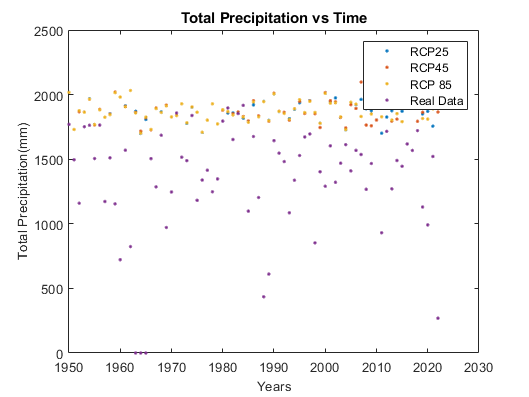

UsefulClimateModelData = [modeldatavar(1:73,:)];
UsefulYearlyAvgData = [YearlyAvg(26:end,:)];
CombinedDataSet = [UsefulClimateModelData UsefulYearlyAvgData(:,2)];

figure(7);
plot(CombinedDataSet(:,1), CombinedDataSet(:,7), '.')
hold on
plot(CombinedDataSet(:,1), CombinedDataSet(:,8), '.')    %COLUMN 1 = YEAR DATES
plot(CombinedDataSet(:,1), CombinedDataSet(:,9), '.')    %COLUMN 7 8 9= RCP 25, 45, 85
plot(CombinedDataSet(:,1), CombinedDataSet(:,10), '.')   %COLUMN 10 = Yearly AVG Total Precip
hold off
legend('RCP25', 'RCP45', 'RCP 85', 'Real Data');
title('Total Precipitation vs Time') ;
xlabel('Years', 'FontSize', 10);
ylabel('Total Precipitation(mm)', 'FontSize', 10);

Below is the function used to find the correlation coefficients between the climate station data and each of the predicted precipitation models. The correlation coefficient is then used to preform a linear regression between the real data and the models which are then plotted along with their corresponding datasets, each shown twice with different axis. 

bc25 = corrcoef(CombinedDataSet(:,7), CombinedDataSet(:,10));
bc45 = corrcoef(CombinedDataSet(:,8), CombinedDataSet(:,10));
bc85 = corrcoef(CombinedDataSet(:,9), CombinedDataSet(:,10));

reg_y25 =  CombinedDataSet(:,7);
reg_y45 =  CombinedDataSet(:,8);
reg_y85 =  CombinedDataSet(:,9);
reg_x= [ones(size(reg_y25)), CombinedDataSet(:,10)];

% Regression Section
[b25,bint25,r25,rint25,stats25] = regress(reg_y25, reg_x);
y_pred25 = reg_x * b25 ;

[b45,bint45,r45,rint45,stats45] = regress(reg_y45, reg_x);
y_pred45 = reg_x * b45 ;

[b85,bint85,r85,rint85,stats85] = regress(reg_y85, reg_x);
y_pred85 = reg_x * b85 ;

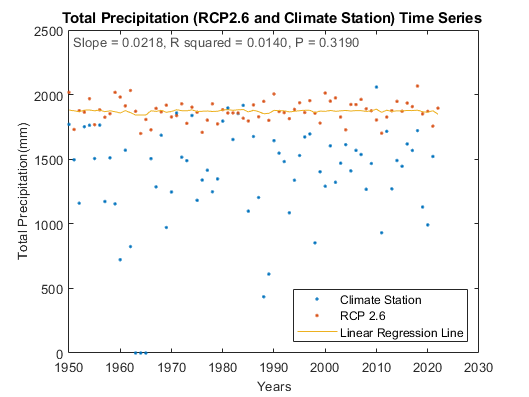

figure(8);
plot(CombinedDataSet(:,1),CombinedDataSet(:,10), '.');
hold on;
plot(CombinedDataSet(:,1),CombinedDataSet(:,7), '.');
plot(CombinedDataSet(:,1), y_pred25);
hold off;
xlabel('Years', 'FontSize', 10);
ylabel('Total Precipitation(mm)', 'FontSize', 10);
title('Total Precipitation (RCP2.6 and Climate Station) Time Series ') ;
legend('Climate Station','RCP 2.6','Linear Regression Line', 'location', 'southeast');
tl_label('Slope = 0.0218, R squared = 0.0140, P = 0.3190');

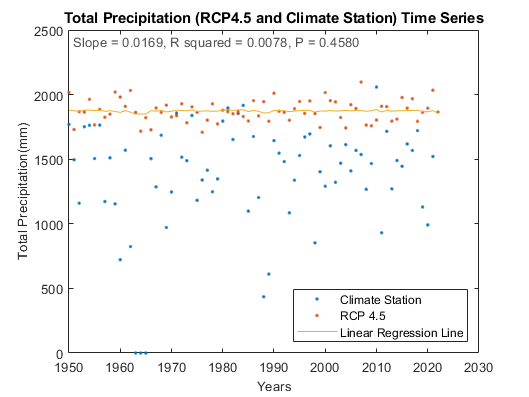



figure(9);
plot(CombinedDataSet(:,1),CombinedDataSet(:,10),'.');
hold on
plot(CombinedDataSet(:,1),CombinedDataSet(:,8),'.');
plot(CombinedDataSet(:,1), y_pred45);
hold off
xlabel('Years', 'FontSize', 10);
ylabel('Total Precipitation(mm)', 'FontSize', 10);
title('Total Precipitation (RCP4.5 and Climate Station) Time Series') ;
legend('Climate Station','RCP 4.5','Linear Regression Line', 'location', 'southeast');
tl_label('Slope = 0.0169, R squared = 0.0078, P = 0.4580');

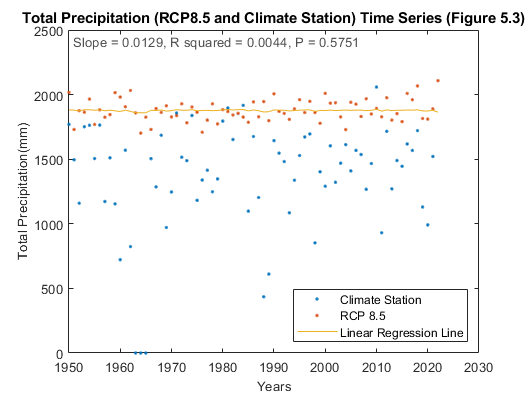


figure(10);
plot(CombinedDataSet(:,1),CombinedDataSet(:,10), '.');
hold on
plot(CombinedDataSet(:,1),CombinedDataSet(:,9), '.');
plot(CombinedDataSet(:,1), y_pred85);
hold off
xlabel('Years', 'FontSize', 10);
ylabel('Total Precipitation(mm)', 'FontSize', 10);
title('Total Precipitation (RCP8.5 and Climate Station) Time Series (Figure 5.3)') ;
legend('Climate Station','RCP 8.5', 'Linear Regression Line', 'location', 'southeast');
tl_label('Slope = 0.0129, R squared = 0.0044, P = 0.5751');

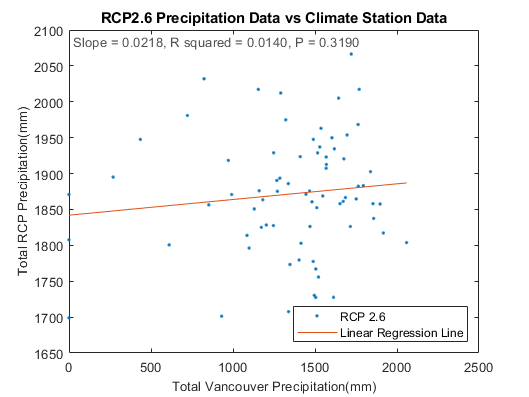

figure(11);
plot(CombinedDataSet(:,10),CombinedDataSet(:,7), '.');
hold on;
plot(CombinedDataSet(:,10), y_pred25);
hold off;
xlabel('Total Vancouver Precipitation(mm)', 'FontSize', 10);
ylabel('Total RCP Precipitation(mm)', 'FontSize', 10);
title('RCP2.6 Precipitation Data vs Climate Station Data') ;
legend('RCP 2.6','Linear Regression Line', 'location', 'southeast');
tl_label('Slope = 0.0218, R squared = 0.0140, P = 0.3190');

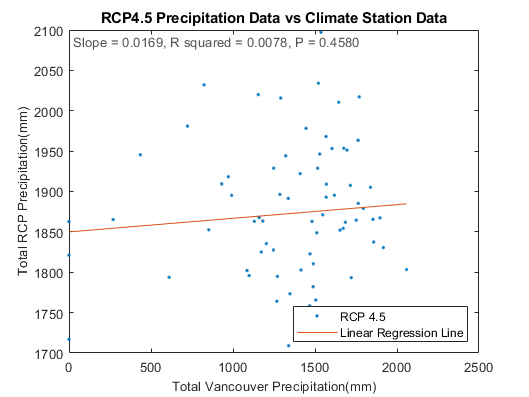


figure(12);
plot(CombinedDataSet(:,10),CombinedDataSet(:,8),'.');
hold on
plot(CombinedDataSet(:,10), y_pred45);
hold off
xlabel('Total Vancouver Precipitation(mm)', 'FontSize', 10);
ylabel('Total RCP Precipitation(mm)', 'FontSize', 10);
title('RCP4.5 Precipitation Data vs Climate Station Data') ;
legend('RCP 4.5','Linear Regression Line', 'location', 'southeast');
tl_label('Slope = 0.0169, R squared = 0.0078, P = 0.4580');

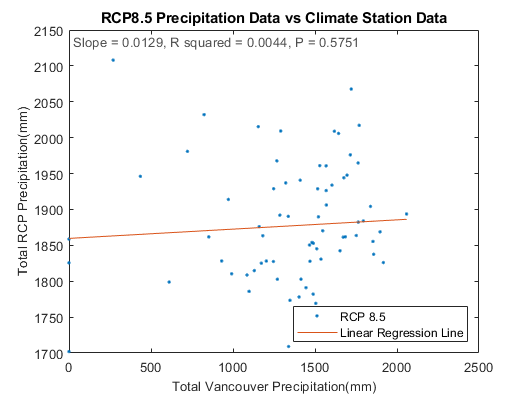


figure(13);
plot(CombinedDataSet(:,10),CombinedDataSet(:,9), '.');
hold on
plot(CombinedDataSet(:,10), y_pred85);
hold off
xlabel('Total Vancouver Precipitation(mm)', 'FontSize', 10);
ylabel('Total RCP Precipitation(mm)', 'FontSize', 10);
title('RCP8.5 Precipitation Data vs Climate Station Data') ;
legend('RCP 8.5', 'Linear Regression Line', 'location', 'southeast');
tl_label('Slope = 0.0129, R squared = 0.0044, P = 0.5751');

Through this research we found that we are unable to confidently state that there is a strong correlation between each of the models and the actual data taken. 

function tl_label(label_string)
sz = 1;
txt = text(0.01,0.99,label_string, ...
'horiz','left','Vert','top','units','normalized','color',[.3 .3 .3]);
txt_fs = get(txt,'fontsize');
set(txt,'fontsize',txt_fs*sz);
end